# `LineGradientChart`** Examples**

**Overview**

The `LineGradientChart` manages a line plot which has an associated color gradient. The chart data comprises an increasing `datetime` vector (`XData`) together with a numeric data vector (`YData`). The `YData` is plotted against the `XData` and the color gradient corresponds to the values contained in `YData`. 

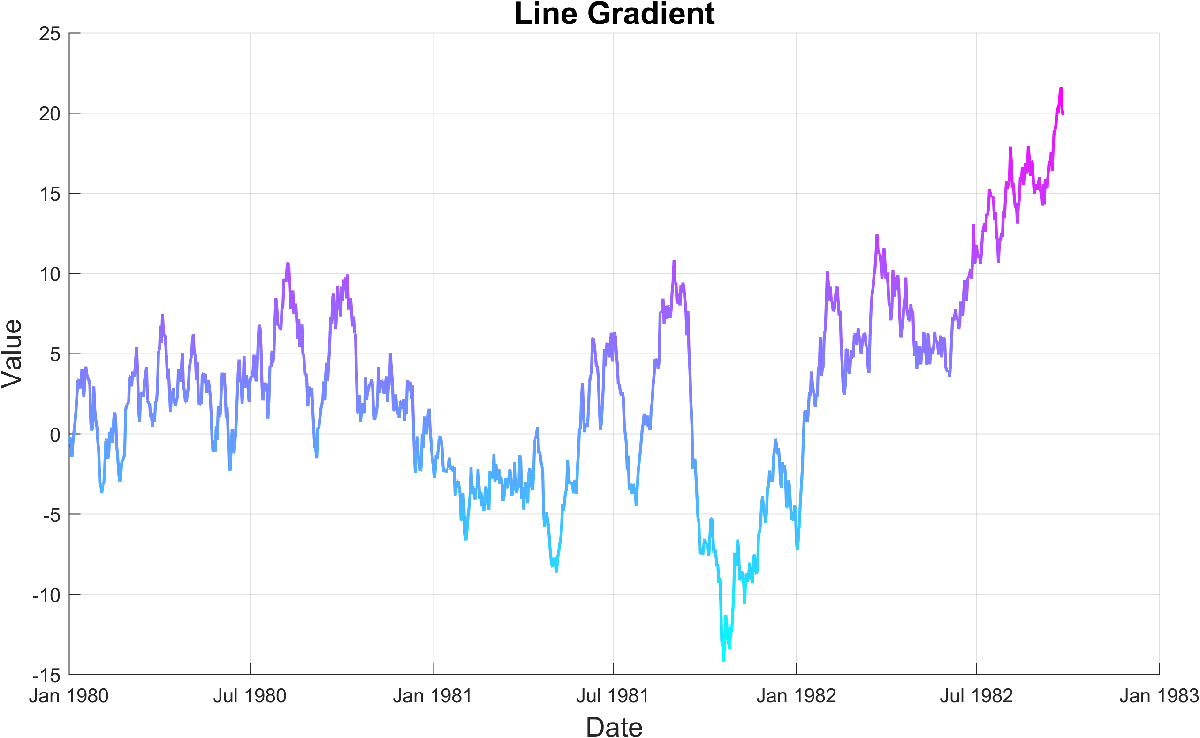

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "LineGradient.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "LineGradient.m"))) the source code for the `LineGradientChart`.

Documentation for:

- [`surface`](matlab: doc("surface")): creates a primitive, three-dimensional surface plot.

## Create data for the chart: dates and a random walk.

dates = datetime( 1970, 1, 1 ) : datetime( 1980, 1, 1 );
rng( "default" )
steps = [0, randn( size( dates(1:end-1) ) )];
walk = cumsum( steps );

## Create a figure for the chart.

f = exampleFigure( "Name", "LineGradientChart Example" );

## Create the chart, specifying the data and figure.

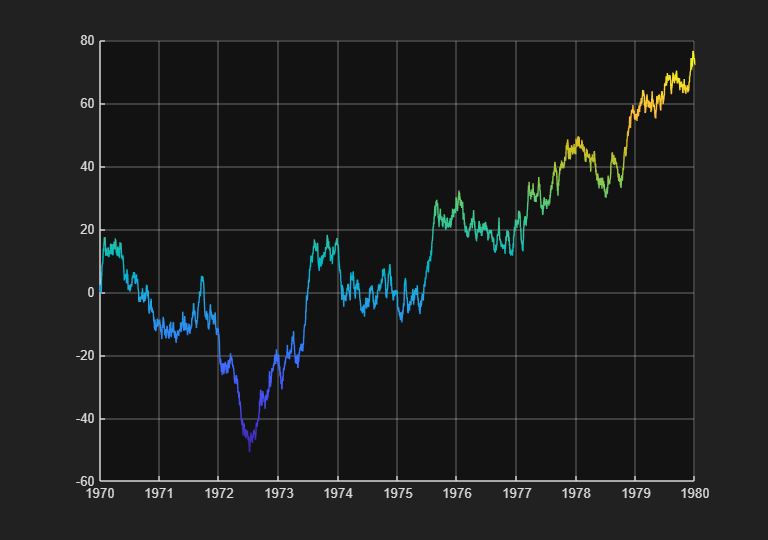

LGC = LineGradientChart( "Parent", f, ...   
    "XData", dates, ...
    "YData", walk );

## Annotate the chart and customize its appearance.

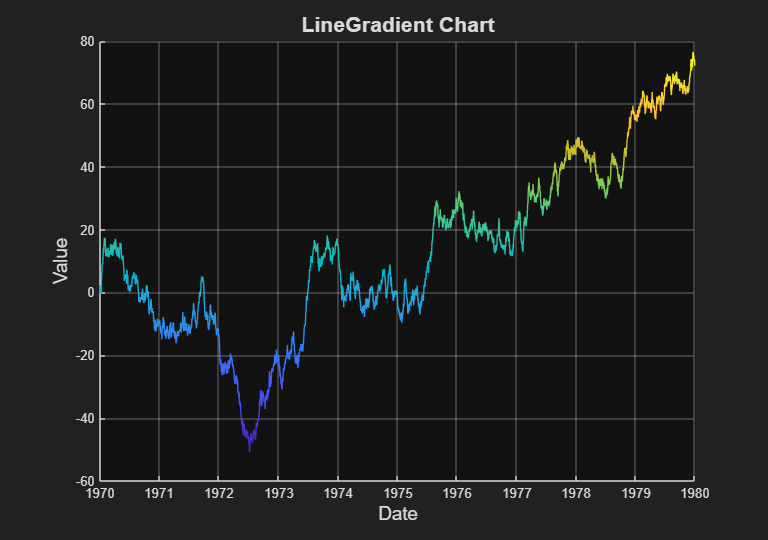

xlabel( LGC, "Date", "FontSize", 14 )
ylabel( LGC, "Value", "FontSize", 14 )
title( LGC, "LineGradient Chart", "FontSize", 16 )

## Adjust the width of the line.

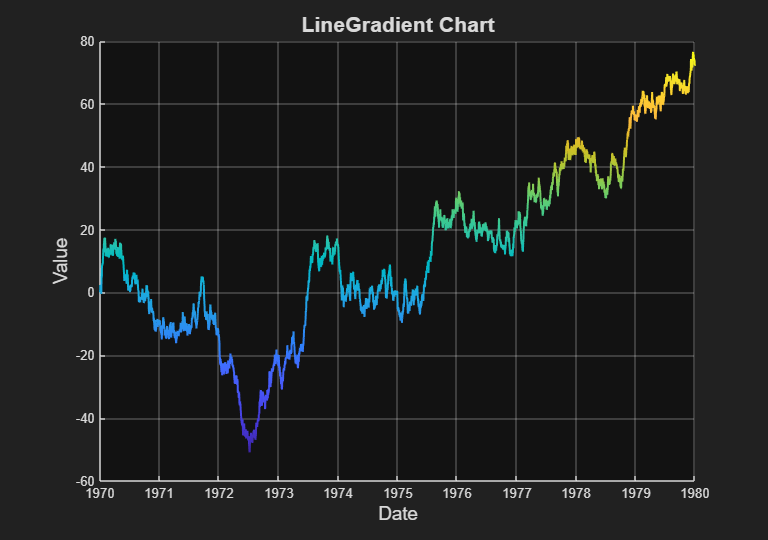

LGC.LineWidth = 1.5;

## Change the colormap.

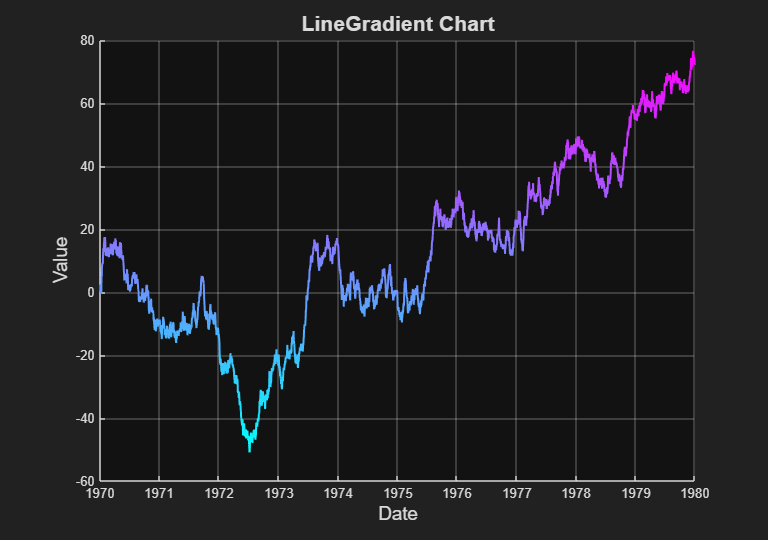

colormap( LGC, cool() )

## Change the x-data of the chart to the first 1000 dates.

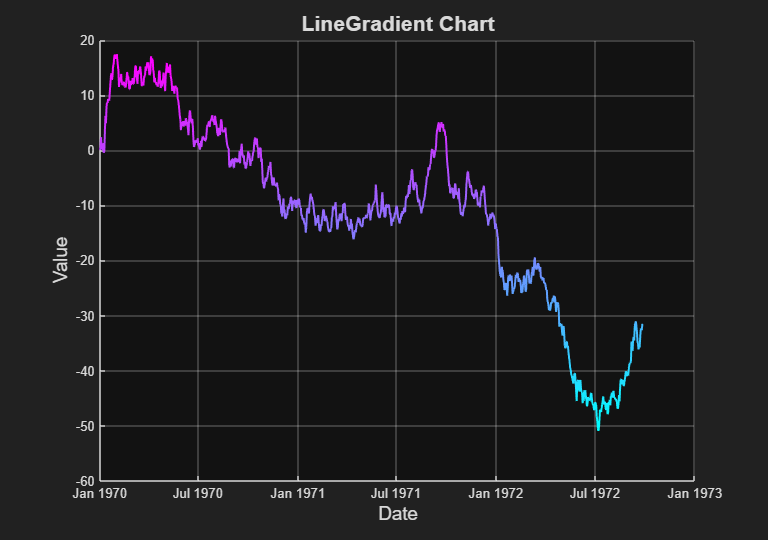

LGC.XData = LGC.XData(1:1000);

## Change the dates by translating by 10 calendar years.

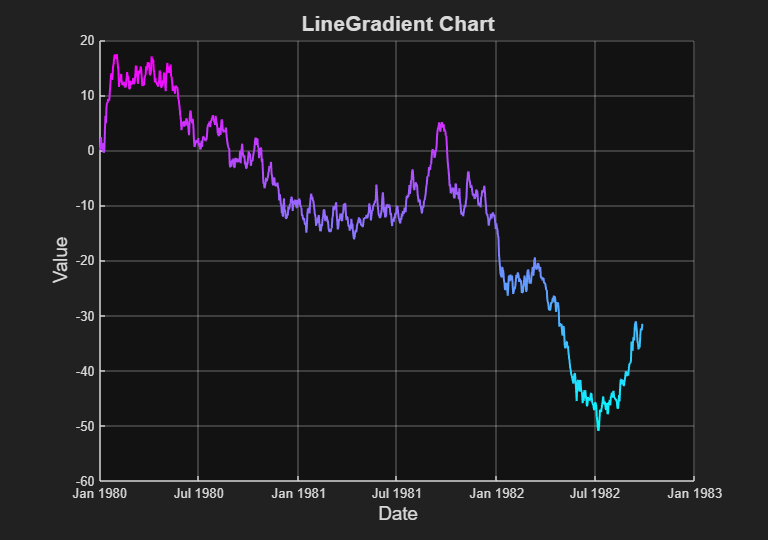

LGC.XData = LGC.XData + calyears( 10 );

## Change the y-data of the chart to a new random walk.

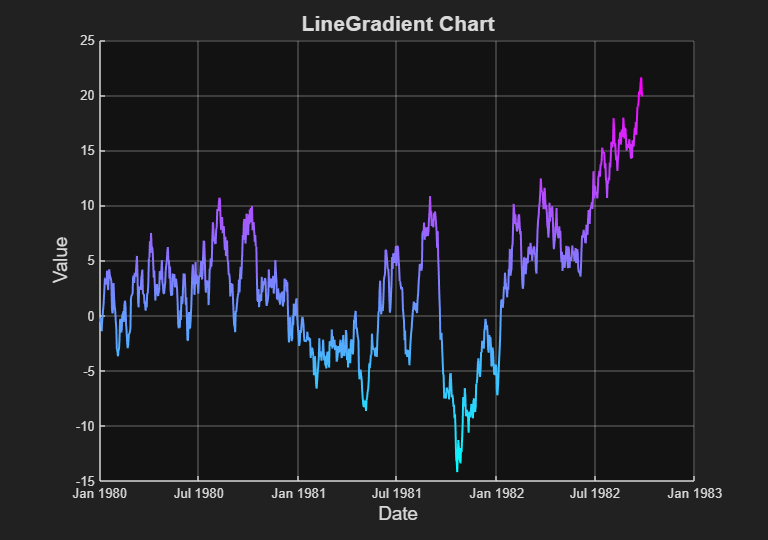

LGC.YData = cumsum( randn( size( LGC.XData ) ) );

*Copyright 2018-2025 The MathWorks, Inc.*